# Compare

clear
jaksa_open_close = importdata("jaksa_open_close.mat");
jaksa_lv_open_close = importdata("jaksa_lv_open_close.mat");

## Displacement

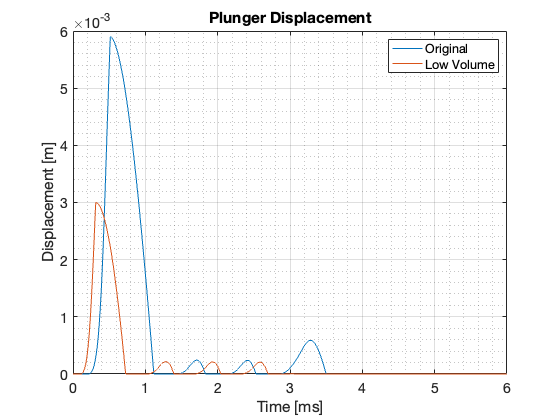

figure('DefaultAxesFontSize',14)
plot(jaksa_open_close.t*10^3,jaksa_open_close.x,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.x)
legend('Original','Low Volume')
grid on, grid minor, xlabel('Time [ms]'), ylabel('Displacement [m]'), title('Plunger Displacement')

## Volume

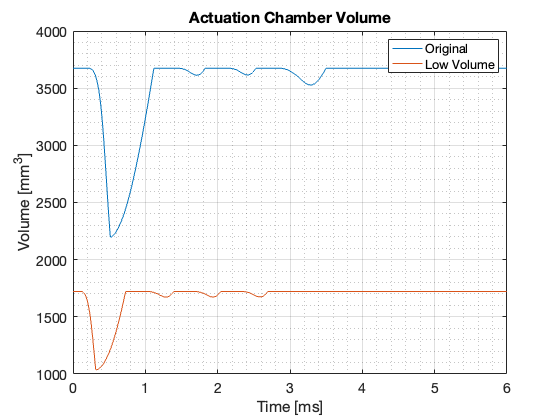

figure('DefaultAxesFontSize',14)
plot(jaksa_open_close.t*10^3,jaksa_open_close.V_ac,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.V_ac)
legend('Original','Low Volume')
grid on, grid minor, xlabel('Time [ms]'), ylabel('Volume [mm^3]'), title('Actuation Chamber Volume')

## Pressures

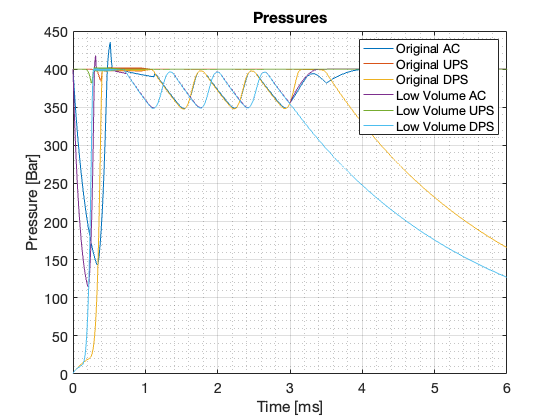

figure('DefaultAxesFontSize',14)
% plot(...
%     jaksa_open_close.t*10^3,jaksa_open_close.P_u,...
%     jaksa_open_close.t*10^3,jaksa_open_close.P_ac,...
%     jaksa_open_close.t*10^3,jaksa_open_close.P_d,...
%     jaksa_open_close.t*10^3,jaksa_open_close.P_dps,...
%     jaksa_open_close.t*10^3,jaksa_open_close.P_ups,...
%     jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.P_u,...
%     jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.P_ac,...
%     jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.P_d,...
%     jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.P_dps,...
%     jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.P_ups...
%     )
%legend('U','AC','D','DPS','UPS','U','AC','D','DPS','UPS')
plot(...
    jaksa_open_close.t*10^3,jaksa_open_close.P_ac,...
     jaksa_open_close.t*10^3,jaksa_open_close.P_ups,...
    jaksa_open_close.t*10^3,jaksa_open_close.P_dps,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.P_ac,...
     jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.P_ups,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.P_dps...
    )
grid on, grid minor, xlabel('Time [ms]'), ylabel('Pressure [Bar]'), title('Pressures')
legend('Original AC','Original UPS','Original DPS',...
    'Low Volume AC','Low Volume UPS','Low Volume DPS')

## Forces

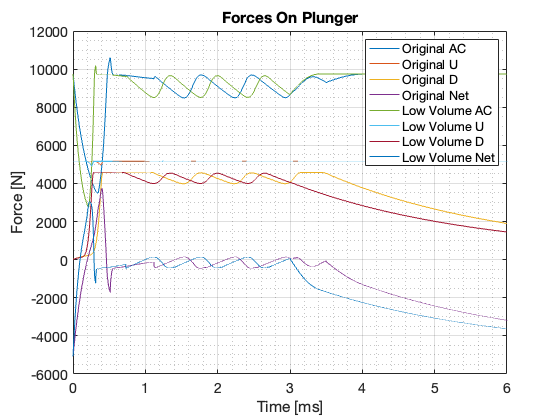

figure('DefaultAxesFontSize',14)
plot(...
    jaksa_open_close.t*10^3,jaksa_open_close.F_ac,...
    jaksa_open_close.t*10^3,jaksa_open_close.F_u,...
    jaksa_open_close.t*10^3,jaksa_open_close.F_d,...
    jaksa_open_close.t*10^3,jaksa_open_close.F,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.F_ac,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.F_u,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.F_d,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.F...
    )
grid on, grid minor, xlabel('Time [ms]'), ylabel('Force [N]'), title('Forces On Plunger')
legend(...
    'Original AC','Original U','Original D','Original Net',...
    'Low Volume AC','Low Volume U','Low Volume D','Low Volume Net'...
    )

## Net force

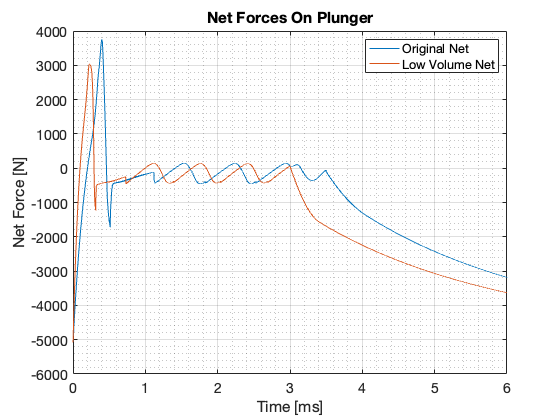

figure('DefaultAxesFontSize',14)
plot(...
    jaksa_open_close.t*10^3,jaksa_open_close.F,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.F...
    )
grid on, grid minor, xlabel('Time [ms]'), ylabel('Net Force [N]'), title('Net Forces On Plunger')
legend(...
    'Original Net',...
    'Low Volume Net'...
    )

## UPD to DPS

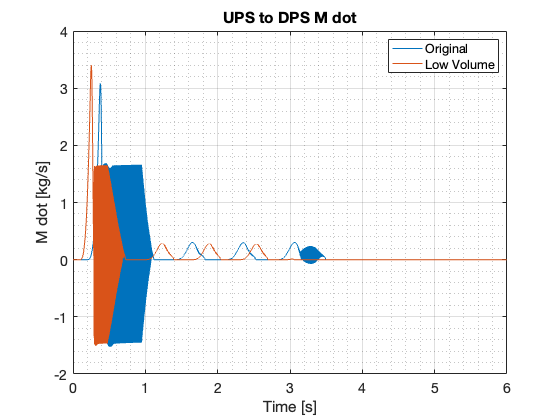

figure('DefaultAxesFontSize',14)
plot(...
    jaksa_open_close.t*10^3,jaksa_open_close.m_dot_ups_dps,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.m_dot_ups_dps...
    )
grid on, grid minor, xlabel('Time [s]'), ylabel('M dot [kg/s]'), title('UPS to DPS M dot')
legend('Original', 'Low Volume')

## AC net m dot

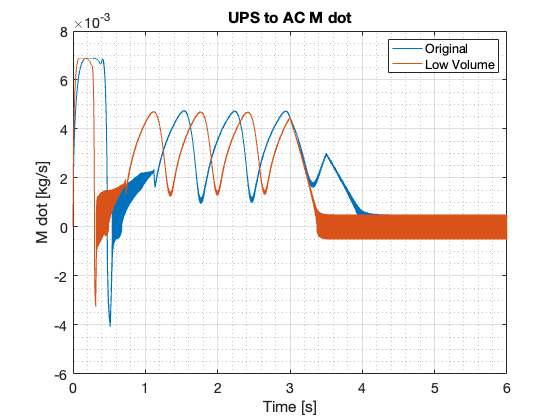

figure('DefaultAxesFontSize',14)
plot(...
    jaksa_open_close.t*10^3,jaksa_open_close.m_dot_ups_ac,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.m_dot_ups_ac...
    )
grid on, grid minor, xlabel('Time [s]'), ylabel('M dot [kg/s]'), title('UPS to AC M dot')
legend('Original', 'Low Volume')